3.3 **3D Stereo**

This is a fairly substantial section as you will need to write a MATLAB function script to compute disparity images (or *maps*) for pairs of rectified stereo images Pl and Pr. The disparity map is inversely proportional to the depth map which gives the distance of various points in the scene from the camera.

a) Write the disparity map algorithm as a MATLAB function script which takes two arguments of left and right images, and 2 arguments specifying the template dimensions. It should return the disparity map. Try and minimize the use of for loops, instead relying on the vector / matrix processing functions.

% TODO

b) Download the synthetic stereo pair images of ‘corridorl.jpg’ and ‘corridorr.jpg’, converting both to grayscale.

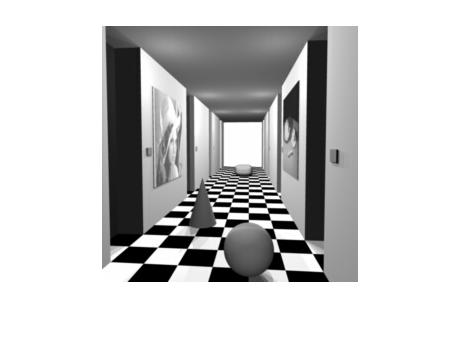

corridorL = imread('images/corridorl.jpg');
corridorL = rgb2gray(corridorL);
imshow(corridorL);

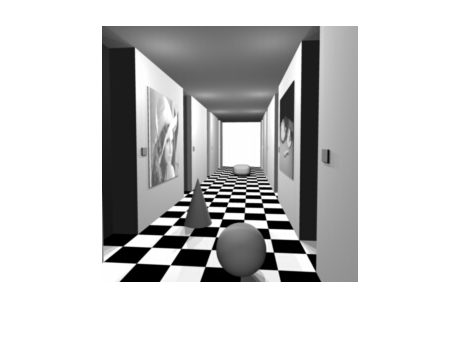


corridorR = imread('images/corridorr.jpg');
corridorR = rgb2gray(corridorR);
imshow(corridorR);

c) Run your algorithm on the two images to obtain a disparity map D, and see the results via

>> imshow(-D,[-15 15]);

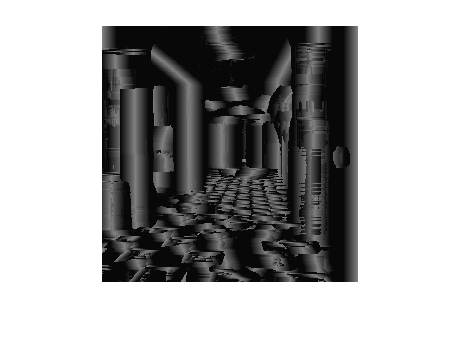

disparityMap = getDisparityMap(corridorL, corridorR, 11, 11);
imshow(-disparityMap, [-15, 15]);

The results should show the nearer points as bright and the further points as dark. The expected quality of the image should be similar to `corridor_disp.jpg’ which you can view for reference.

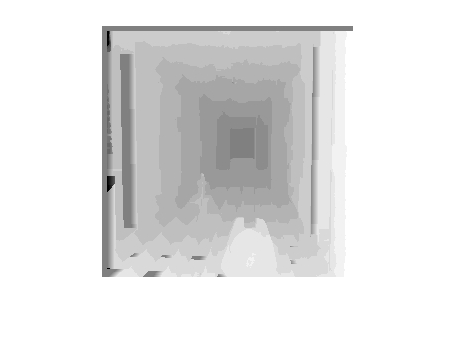

reference = imread('images/corridor_disp.jpg');
imshow(reference);

Comment on how the quality of the disparities computed varies with the corresponding local image structure.

d) Rerun your algorithm on the real images of ‘triclops-i2l.jpg’ and triclops-i2r.jpg’. Again you may refer to ‘triclops-id.jpg’ for expected quality. How does the image structure of the stereo images affect the accuracy of the estimated disparities?

% TODO